Compute NHTD

clear;
clf;
currentDir = pwd;
idx = strfind(currentDir, 'ITPC');
if isempty(idx)
    error('Run this inside the ITPC folder');
end
rootFolder = currentDir(1:idx + length('ITPC') - 1);
addpath(genpath(fullfile(rootFolder, '..')));
dataPath = fullfile(rootFolder, 'Tutorialdataset2');

files = dir(fullfile(dataPath, '*.mat'));
allData = cell(numel(files),1);

for k = 1:numel(files)
    % Remove .mat extension to use as a field name
    [~, fileName] = fileparts(files(k).name);
    % Load all variables from the file
    allData{k} = load(fullfile(folder, files(k).name));
end

% condition x subject x channel x frequency x time 
%A = zeros(2,14,64,61,72); 

% frequency x time x channel x subject x condition
A = zeros(61,72,64,14,2); 
for k = 1:numel(files)
    % Remove .mat extension to use as a field name
    [~, fileName] = fileparts(files(k).name);
    % Load all variables from the file
    slice = load(fullfile(folder, files(k).name));
    if (k >=1 && k<=14)
        A(:,:,:,k,1) = abs(permute(slice.WT,[2,3,1])); %take modulus
    else 
        A(:,:,:,k-14,2) = abs(permute(slice.WT,[2,3,1])); 
    end
end

% HT approximation of tensor A
opts.max_rank = 60;
A_ht = truncate(A,opts); 
A_htFull = full(A_ht);
% Explained Variance 
% (see Extracting multi-mode ERP features using fifth-order nonnegative tensor decomposition)
expvar = 1 - norm(A_htFull - A, 'fro').^2/norm(A,'fro').^2

expvar = 0.9669


ranks = 1:50; 
relErr = zeros(numel(ranks),1); 
tic
normA = norm(A,'fro'); 
for k = 1:numel(ranks)
    r = ranks(k)*ones(1,2*ndims(A_ht)-1); 
    %X = nhtd_mu(A_ht,'rank',r,'max_it',2000,'print',false); 
    X = nhtd_mu(A_ht,'rank',r,'max_it',5000,'print',false); 
    relErr(k) = norm(A - full(X), 'fro')/normA; 
    toc
end 

it = 1001

Elapsed time is 7.818106 seconds.
Elapsed time is 30.049661 seconds.
Elapsed time is 51.416829 seconds.
Elapsed time is 73.361725 seconds.
Elapsed time is 96.254516 seconds.
Elapsed time is 119.165246 seconds.
Elapsed time is 143.038732 seconds.
Elapsed time is 166.660575 seconds.
Elapsed time is 191.784532 seconds.
Elapsed time is 218.610178 seconds.
Elapsed time is 245.783526 seconds.
Elapsed time is 272.785419 seconds.
Elapsed time is 301.948614 seconds.
Elapsed time is 332.249777 seconds.
Elapsed time is 364.675272 seconds.
Elapsed time is 396.937190 seconds.
Elapsed time is 430.749673 seconds.
Elapsed time is 468.107884 seconds.
Elapsed time is 507.907251 seconds.
Elapsed time is 547.098467 seconds.
Elapsed time is 588.771114 seconds.
Elapsed time is 631.366333 seconds.
Elapsed time is 675.726544 seconds.
Elapsed time is 720.446356 seconds.
Elapsed time is 768.829006 seconds.
Elapsed time is 818.833202 seconds.
Elapsed time is 870.989661 seconds.
Elapsed time is 925.152622 seconds

toc

Elapsed time is 3448.077902 seconds.


Load relErr and ranks from 'rank selection' folder.

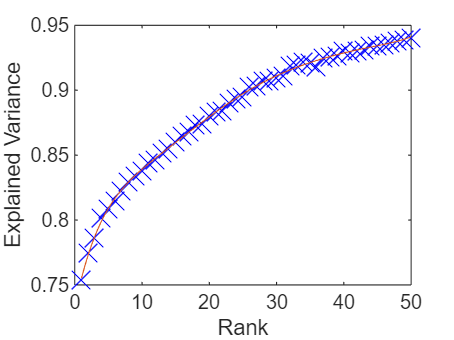

figure;
ev = 1- relErr.^2; 
pol = polyfit(ranks,ev,7); 
x = linspace(min(ranks),max(ranks),100); 
poly_vals = polyval(pol,x); 
plot(ranks,ev,'bx','MarkerSize',12)
hold on
plot(x,poly_vals, '-')
hold off
xlabel('Rank'); ylabel('Explained Variance'); 
ev_pcf = polyval(pol,ranks); 
%save('relErr.mat','relErr')
%save('ranks.mat','ranks')
exportgraphics(gcf, 'ev_plot.pdf', 'ContentType', 'vector')

Following: Extracting multi-mode ERP features using fifth-order nonnegative tensor decomposition

Based on the smoothed DIF and DIFFIT plots, we select the HT ranks to be a constant 15. 

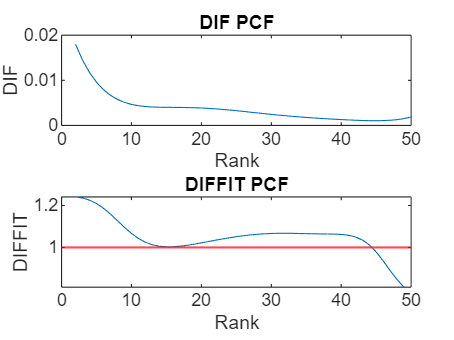

dif = diff(ev_pcf); 
diffit = dif(1:end-1)./dif(2:end); 
figure;

subplot(2,1,1)
plot(ranks(2:end),dif)
title('DIF PCF')
xlabel('Rank'); ylabel('DIF'); 

subplot(2,1,2)
plot(ranks(2:end-1),diffit)
hold on
yline(1, 'r', 'LineWidth', 1)   % horizontal red line
hold off
title('DIFFIT PCF')
xlabel('Rank'); ylabel('DIFFIT'); 
exportgraphics(gcf, 'DIFFIT_PCF.pdf', 'ContentType', 'vector')

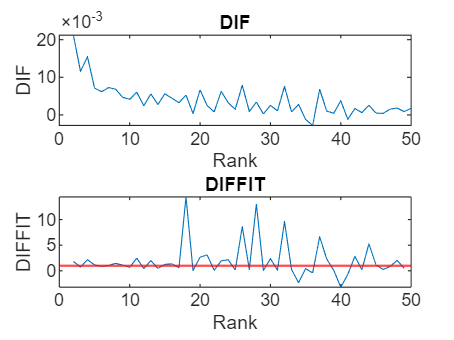

dif = diff(ev); 
diffit = dif(1:end-1)./dif(2:end); 
figure;
subplot(2,1,1)
plot(ranks(2:end),dif)
title('DIF')
xlabel('Rank'); ylabel('DIF'); 

subplot(2,1,2)
plot(ranks(2:end-1),diffit)
hold on
yline(1, 'r', 'LineWidth', 1)   % horizontal red line
hold off
title('DIFFIT')
xlabel('Rank'); ylabel('DIFFIT'); 
exportgraphics(gcf, 'DIFFIT.pdf', 'ContentType', 'vector')